## 导入并预处理数据

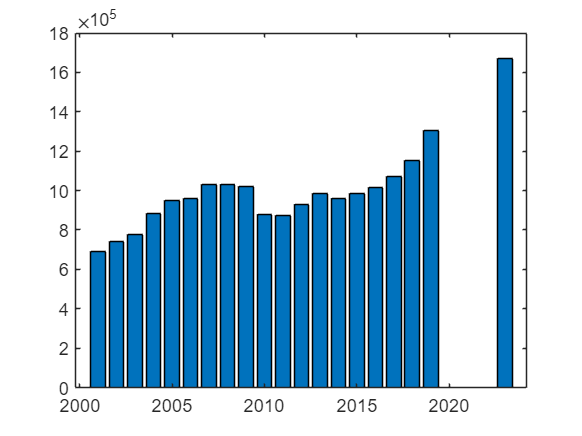

clear, clc;
data=load("D:\个人资料\大学\数学建模\COMAP\COMAP\2025\B\data.mat");  %导入人数
data=table2array(data.data);
data(20,2)=NaN;  data(21,2)=NaN;  data(22,2)=NaN;
bar(data(:,1),data(:,2));

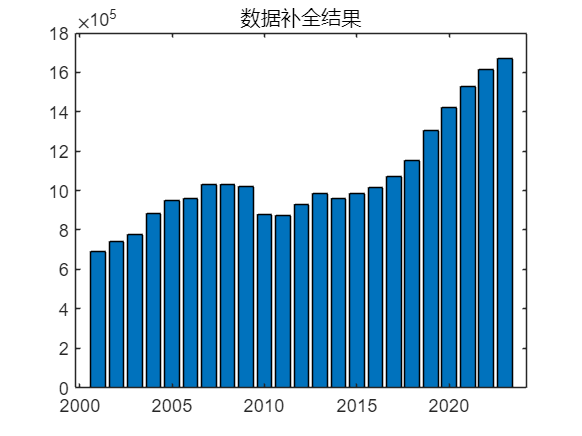

% 1.线性插值 linear 2.分段三次样条插值 spline 3.保形分段三次样条插值 pchip 4.移动滑窗插补 movmean
chazhi_fa = char('linear', 'spline', 'pchip', 'movmean');
choice_2 = 3;
if choice_2 ~= 4
    data = fillmissing(data,strtrim(chazhi_fa(choice_2,:))); % strtrim 是为了去除字符串组的空格
else
    data = fillmissing(data,'movmean',10); % 窗口长度为 10 的移动均值
end
bar(data(:,1),data(:,2));
title('数据补全结果');

ADF检验结果:
是否拒绝原假设（序列非平稳）: 0
p值: 0.9990
KPSS检验结果:
是否拒绝原假设（序列平稳）: 0
p值: 0.0100


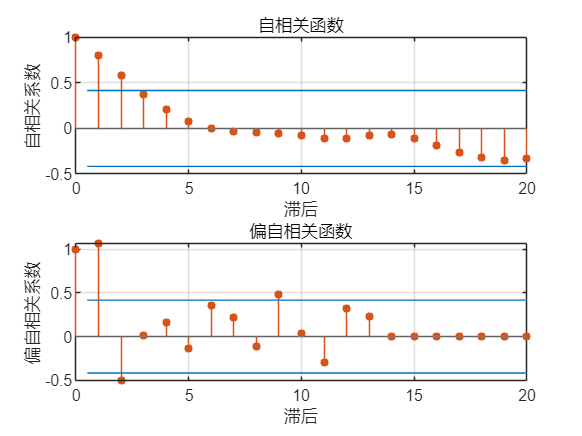

 
    ARIMA(2,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue 
                __________    _____________    __________    _______

    Constant         23558         25963           0.9074     0.3642
    AR{1}         -0.14644       0.78973         -0.18543    0.85289
    AR{2}          0.52688       0.36695           1.4358    0.15105
    MA{1}          0.68318       0.73633          0.92781     0.3535
    Variance    3.5302e+09       0.22928       1.5397e+10          0




% 时间序列预测测试
y=data(:,2); PreTime=100;
forecastTest=ARIMA(PreTime,y);

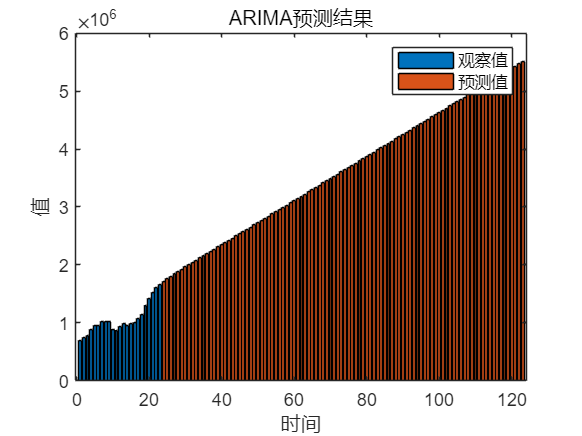

figure;  bar(y);  hold on;
time_axis = (length(y)+1:length(y)+PreTime)';
bar(time_axis, forecastTest);
xlabel('时间');  ylabel('值');
legend('观察值', '预测值');  title('ARIMA预测结果');

## 优化模型

f=@(alpha)-Revenue1(alpha,PreTime)

f = 包含以下值的 function_handle :
    @(alpha)-Revenue1(alpha,PreTime)


x0=[1e5;0*ones(PreTime,1);0*ones(PreTime,1)];
A=[zeros(PreTime,1),eye(PreTime),eye(PreTime)];
b=0.5*ones(PreTime,1);
lb=zeros(2*PreTime+1,1);  ub=[1e9;0.5*ones(2*PreTime,1)];
[x,fmin]=fmincon(f,x0,A,b,[],[],lb,ub);


可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>


Nmax=x(1)

Nmax = 9.9999e+04

alpha=[x(2:PreTime+1),x(PreTime+2:end)]

alpha =     0.1958    0.2143
    0.1807    0.2308
    0.2172    0.1998
    0.1218    0.2941
    0.2069    0.2053
    0.1915    0.2282
    0.2118    0.1960
    0.2216    0.2036
    0.2244    0.1922
    0.2085    0.2099


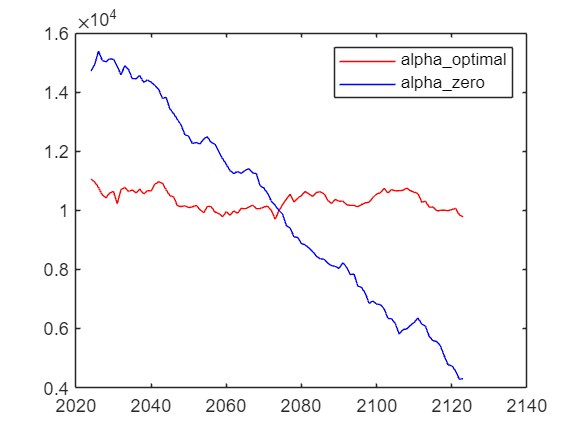

[R,Rt,S,C,I,N]=Revenue1(x,PreTime);
[R0,Rt0,S0]=Revenue1([1e5;linspace(0.03,0,3)';0*ones(97,1);linspace(0.03,0,3)';0*ones(97,1)],PreTime);
figure; plot(2024:2023+PreTime,Rt,'r',2024:2023+PreTime,Rt0,'b');
legend('alpha\_optimal','alpha\_zero');


% f=@(alpha)-Revenue2(alpha,PreTime,forecastTest)
% x0=[1e5;0*ones(PreTime,1);0*ones(PreTime,1)];
% A=[zeros(PreTime,1),eye(PreTime),eye(PreTime)];
% b=0.5*ones(PreTime,1);
% lb=zeros(2*PreTime+1,1);  ub=[1e9;0.5*ones(2*PreTime,1)];
% [x,fmin]=fmincon(f,x0,A,b,[],[],lb,ub);
% Nmax=x(1)
% alpha=[x(2:PreTime+1),x(PreTime+2:end)]
% [R,Rt,S,C,I,N]=Revenue2(x,PreTime,forecastTest);
% [R0,Rt0,S0]=Revenue2([1e5;0*ones(PreTime,1);0*ones(PreTime,1)],PreTime,forecastTest);
% figure; plot(1:PreTime,Rt,'r',1:PreTime,Rt0,'b');
% legend('alpha\_optimal','alpha\_zero');

## 目标函数（1）maxR s.t. Nmax>0, 0<=alpha_1(t)+alpha_2(t)<=alpha_max

function [R,Rt,S,C,I,N]=Revenue1(alpha,PreTime)  %alpha1为碳alpha2为基础
    %参数
    Nmax=alpha(1);  alpha_1=alpha(2:1+PreTime);  alpha_2=alpha(2+PreTime:end);
    P0=490/1.67;  N0=1.67e6;  S0=0.5;  Ep=-1;
    Cmean=14.4;  Imean=1;  C0=1e5;  I0=1e5;
    r1=2/pi;  r2=1e-4;  k1=100;  k2=100;
    lambda=[0.8;0.1;0.1];  %可持续性因子权重

    N=zeros(PreTime,1);  Rt=zeros(PreTime,1);
    S=zeros(PreTime,1);  I=zeros(PreTime,1);
    C=zeros(PreTime,1);

    N(1)=N0*(1+alpha_1(1)+alpha_2(1))^Ep+0.5*randn(1);
    N(1)=min([Nmax,r1*N(1)*atan(r2*S0)]);
    Rt(1)=P0*N(1);

    %可持续性因子，未作单位化处理; Satis为满意度函数，Rt为收入，N为人数
    I(1)=I0+k2*alpha_2(1)*P0*N(1);  C(1)=Cmean*N(1);
    S(1)=[C0/Cmean*N(1),I(1)/Imean*N(1),Rt(1)/N(1)]*lambda;
    for t=2:PreTime
        N(t)=N(t-1)*((1+alpha_1(t)+alpha_2(t))/(1+alpha_1(t-1)+alpha_2(t-1)))^Ep+0.5*randn(1);
        N(t)=min([Nmax,r1*N(t)*atan(r2*S(t-1))]);
        Rt(t)=P0*N(t);  

        C(t)=Cmean*N(t)-k1*alpha_1(t-1)*P0*N(t-1);
        I(t)=I(t-1)+k2*alpha_2(t-1)*P0*N(t-1);
        S(t)=[C0/C(t),I(t)/Imean*N(t),Rt(t)/N(t)]*lambda;
    end
    R=sum(Rt);
end

## 目标函数（2）maxR s.t. Nmax>0, 0<=alpha_1(t)+alpha_2(t)<=alpha_max

function [R,Rt]=Revenue2(alpha,PreTime,N0)
    %参数,统一使用列向量
    Nmax=alpha(1);  alpha_1=alpha(2:1+PreTime);  alpha_2=alpha(2+PreTime:end);
    P0=490/1.67;  S0=0.5;  Ep=-1; 
    Cmean=14.4;  Imean=1;  C0=1e5;  I0=1e5;
    r1=2/pi;  r2=1e-4;  k1=100;  k2=100;
    lambda=[0.8;0.1;0.1];  %可持续性因子权重

    N=zeros(PreTime,1);  Rt=zeros(PreTime,1);
    S=zeros(PreTime,1);  I=zeros(PreTime,1);

    %时间序列预测
    N(1)=ARIMA(1,N0);    %ARIMA为时间序列预测
    N(1)=N(1)*(1+alpha_1(1)+alpha_2(1))^Ep;
    N(1)=min([Nmax,r1*N(1)*atan(r2*S0)]);
    Rt(1)=P0*N(1);

    %可持续性因子，未作单位化处理; Satis为满意度函数，Rt为收入，N为人数
    I(1)=I0+k2*alpha_2(1)*P0*N(1);  C(1)=Cmean*N(1);
    S(1)=[C0/Cmean*N(1),I(1)/Imean*N(1),Rt(1)/N(1)]*lambda;
    N0=[N0;N(1)];
    for t=2:PreTime
        N(t)=ARIMA(1,N0);
        N(t)=N0(end)*(1+alpha_1(t)+alpha_2(t))^Ep;
        N(t)=max([Nmax,r1*N(t)*atan(r2*S(t-1))]);
        Rt(t)=P0*N(t);

        C(t)=Cmean*N(t)-k1*alpha_1(t-1)*P0*N(t-1);
        I(t)=I(t-1)+k2*alpha_2(t-1)*P0*N(t-1);
        S(t)=[C0/C(t),I(t)/Imean*N(t),Rt(t)/N(t)]*lambda;
    end
    R=sum(Rt);
end

## ARIMA算法

function forecastTest=ARIMA(PreTime,y)

% 拆分数据集为训练集和测试集
train_size = floor(0.8 * length(y));
train_data = y;

% 平稳性检验 - ADF检验
[h_adf, p_adf] = adftest(y);
fprintf('ADF检验结果:\n');
fprintf('是否拒绝原假设（序列非平稳）: %d\n', h_adf);
fprintf('p值: %.4f\n', p_adf);
 
% 平稳性检验 - KPSS检验
[h_kpss, p_kpss] = kpsstest(y);
fprintf('KPSS检验结果:\n');
fprintf('是否拒绝原假设（序列平稳）: %d\n', ~h_kpss);
fprintf('p值: %.4f\n', p_kpss);
 
% 确定参数
y_diff = train_data;
figure;
subplot(2,1,1);  autocorr(y_diff);
title('自相关函数');  xlabel('滞后');  ylabel('自相关系数');
subplot(2,1,2);  parcorr(y_diff);
title('偏自相关函数');  xlabel('滞后');  ylabel('偏自相关系数');
 
% 训练ARIMA模型
model = arima(2, 1, 1);
model = estimate(model, y_diff);
 
% 测试未来时间预测情况
horizon = PreTime;
[forecastTest, YMSE, forecastCI] = forecast(model, horizon, 'Y0', y_diff);
%ResultScale(:, 1) = forecastTest - 1.64*sqrt(YMSE); % 90%置信区间下限
%ResultScale(:, 2) = forecastTest + 1.64*sqrt(YMSE); % 90%置信区间上限
end